**Method 1: Adaptive filtering (entailing the LMS algorithm)**

The first method that I'm going to try and employ in order to remove or at least weaken the noise/interference is an adaptive filtering one. We'll try and minimise the mean square error between the mixed signal, and our filter output. The error at each time step will act to tweak our filter coefficients, so that it's better able to predict the narrowband (noise/interference) signal. 

[SoundData, fs] = audioread('noisy_voices.WAV'); % Reading the signal in...

Error using audioread (line 90)
The filename specified was not found in the MATLAB path.


Ts = 1/fs; % The sampling period...
t_vector = Ts:Ts:numel(SoundData(1:50000))*Ts % The time vector...

plot(abs(fft(SoundData(1:100000))))
pwelch(SoundData)
% plot(t_vector, SoundData(1:50000))
% title('\bf\fontname{Georgia}Signal in the Time Domain')
% ylabel('\bf\fontname{Georgia}Signal Value')
% xlabel('\bf\fontname{Georgia}Time (Seconds)')
% set(gca,'Fontname', 'Georgia');

x = SoundData'; % Our signal...

delayVal = 2500; % How long we wan't to delay our signal...

order = 90; % Filter order that we're going to use...

h0 = randi(100, 1, order); % The initial filter coefficients, which we're generating at random...

% I've defined a function (called 'h_gen( )') which generates the new or updated filter
% coefficients based on the current ones, the current error, and the
% delayed input signal: this is in direct accordance with the formula
% discussed in the lectures...

x_delayed = [zeros(1, delayVal) x]; % Delaying our signal by padding it with zeros...

% Now, as our signal isn't defined for negative indexes, I'm simply
% appending an appropiate number of zeros at the beginning, so that when
% implementing the formula for the filter output, each of these would-be
% negative indexes evaluate to zero...
x_ext = [zeros(1, delayVal + order) x_delayed];

x_hat = zeros(1, numel(x)) % Our currently empty x_hat vector, which is the output from the
% ADF filter...

alpha = 0.5; % The alpha that appears in the expression for updating or 'adapting' the
% the filter coefficients...
h = zeros(1, order); % This represents the subsequent vector of filter coefficients...

for i = 1:numel(x)
    count = 0; % A count variable...
    if i == 1
        h = h0; % We have to initially guess the filter coefficients...
    else
        x_delayVec = flip(x_ext(i:order + i - 1)); % This is a vector of values corresponding to: x(n-N-j)...
        h = h_gen(h, alpha, error, x_delayVec); % This function updates the filter coefficient array for each new time step...
    end
    
    for k = 1:order % i.e. for 1 to the order of our filter...
        count = count + h(k)*x_ext(order + i - k); % i.e. h1*x_(n-N) + h2*x_(n-N-1) + ...
    end
    
    x_hat(i) = count; % Fill in the x_hat vector, the output from our adaptive filter...
    error = x(i) - x_hat(i); % Compute the error at the ith time step...
end

x_BroadBand = x - x_hat; % In accordance with the block diagram discussed during lectures...

soundsc(x_BroadBand, fs)

One can play around with the delay value as well as the filter order to see the effects. One thing I noticed, however, was that by increasing the magnitude of the initial filter coefficients, the result improved. That's why in the randi( ) statement, I've set the upper limit to 100... it improved the overall noise or interference reduction.

**Method 2: Spectral Subtraction**

The second method that I'm going to try and use to clean the mixed signal from the noise or interference is the so-called* spectral subtraction method - *from consulting onlines resources it seems to be one of the oldest and most popular methods for speech enhancement. The reason I like it is the straightforwardness of it, it seems direct and practical. Before we start coding-in the algorithm, however, I just want to briefly discuss my general approach below:

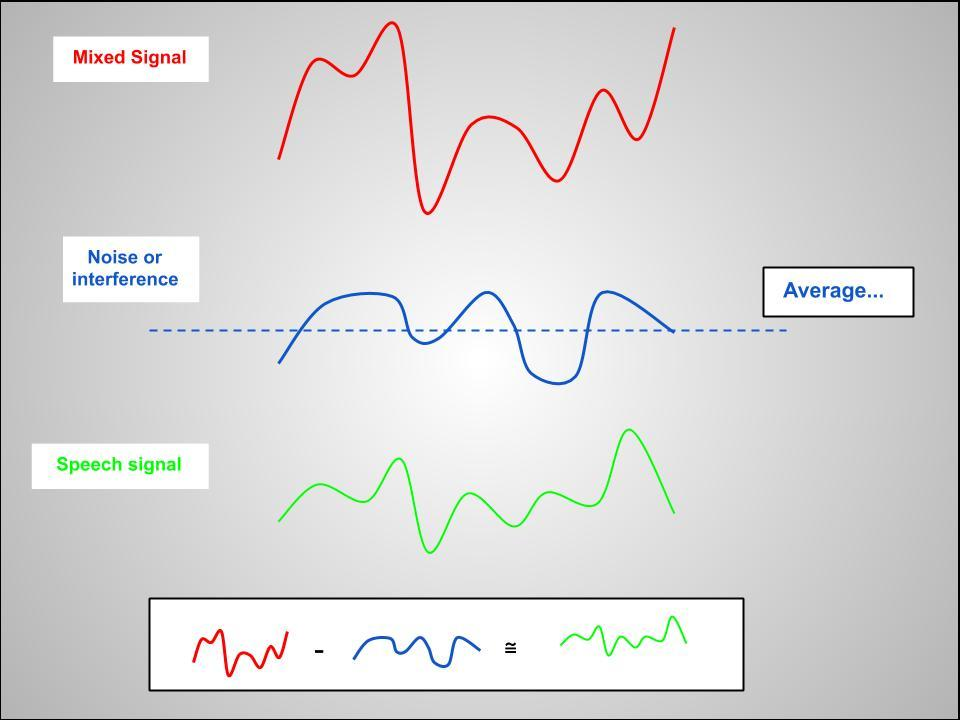

We can describe the above idea in more mathematical temrs, and from there generate a nice block diagram which will describe what's going on:


$$S_{\textrm{mixed}} \left(t\right)=S_{\textrm{speech}} \left(t\right)+S_{\textrm{noise}} \left(t\right)$$


Now, a nice property of linearity is that we can say the following:


$$S_{\textrm{mixed}} \left(f\right)=S_{\textrm{speech}} \left(f\right)+S_{\textrm{noise}} \left(f\right)\gets \textrm{Linearity}\;\textrm{applies}\;\textrm{to}\;\textrm{the}\;\textrm{Fourier}\;\textrm{transform}\ldotp \ldotp \ldotp$$


Now, if we could estimate the power spectrum of the noise, then the spectrum of the speech signal would be:


$${\left|S\right.}_{\textrm{speech}} {\left(f\right)}^2 \left|\approx \right|S_{\textrm{mixed}} {\left(f\right)}^2 \left|-E\left\lbrack \left|S_{\textrm{noise}} {\left(f\right)}^2 \right|\right\rbrack \gets \textrm{We}\;\textrm{need}\;\textrm{to}\;\textrm{come}\;\textrm{up}\;\textrm{with}\;\textrm{the}\;\textrm{expected}\;\textrm{value}\;\left(\textrm{average}\right)\;\textrm{of}\;\textrm{the}\;\textrm{noise}\;\textrm{power}\;\textrm{spectrum}\ldotp \ldotp \ldotp \right.$$


Of course, we'd then need to take the square root of this new sequence, and then reincorporate the phase information, giving us:


$$S_{\textrm{speech}} \left(f\right)\approx {\left\lbrack \left|S_{\textrm{mixed}} {\left(f\right)}^2 \right|-E\left\lbrack \left|S_{\textrm{noise}} {\left(f\right)}^2 \right|\right\rbrack \right\rbrack }^{\frac{1}{2}} \left(e^{j\phi } \right)\gets \textrm{This}\;\textrm{will}\;\textrm{result}\;\textrm{in}\;a\;\textrm{complex}-\textrm{valued}\;\textrm{array},\textrm{which}\;{\textrm{we}}^{\prime } \textrm{ll}\;\textrm{apply}\;\textrm{the}\;\textrm{IFFT}\;\textrm{algorithm}\;\textrm{to}\ldotp \ldotp \ldotp$$


In order to better gauge the noise spectrum, we'll parse our big sequence into smaller ones, and deal with one at a time. When it comes to algorithms, I feel a picture usually tells the story better than words - so hopefully the diagram below is clearer!

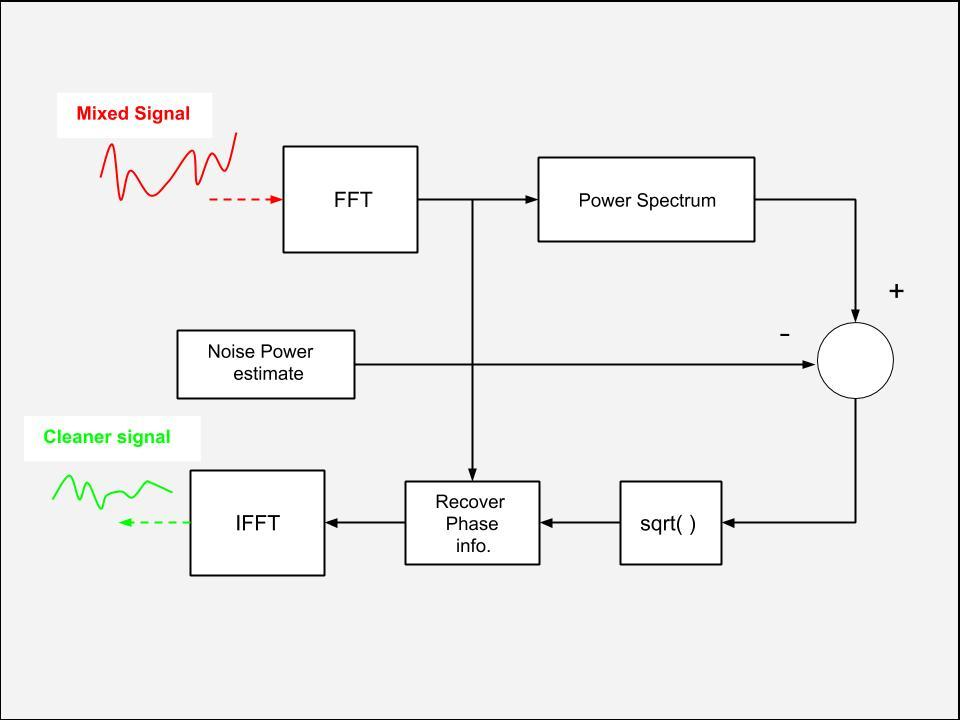

[SoundData, fs] = audioread('noisy_voices.WAV');

% Let's break our big sequence into smaller ones...
seg1 = SoundData(1:50000);
seg2 = SoundData(50001:100001);
seg3 = SoundData(100002:150002);
seg4 = SoundData(150003:200003);
seg5 = SoundData(200004:end);

% This is a frequency vector which might come in handy later for plotting
% purposes...
F_vector = [-50000/2:50000/2-1]*fs/50000

Pspectrum_seg1 = abs(fft(seg1)); % Computing the power spectrum of the first segment...
figure(1)
plot(Pspectrum_seg1)
title('\bf\fontname{Georgia}Power Spectrum of Segment_{1}')
ylabel('\bf\fontname{Georgia}Power');
xlabel('\bf\fontname{Georgia}sample');
set(gca,'Fontname', 'Georgia');

% We're estimating the average value of the noise power spectrum for segement 1... it's
% narrowband, and looks to be be located in the top right-hand corner of
% the spectrum... between index 42500 and 48600...
averageNoise_seg1 = mean(Pspectrum_seg1(42500:48600))

% And we're going to same as above for all the other segments...
Pspectrum_seg2 = abs(fft(seg2));
figure(2)
plot(Pspectrum_seg2)
title('\bf\fontname{Georgia}Power Spectrum of Segment_{2}')
ylabel('\bf\fontname{Georgia}Power');
xlabel('\bf\fontname{Georgia}sample');
set(gca,'Fontname', 'Georgia');

averageNoise_seg2 = mean(Pspectrum_seg2(42500:48600))

Pspectrum_seg3 = abs(fft(seg3));
figure(3)
plot(Pspectrum_seg3)
title('\bf\fontname{Georgia}Power Spectrum of Segment_{3}')
ylabel('\bf\fontname{Georgia}Power');
xlabel('\bf\fontname{Georgia}sample');
set(gca,'Fontname', 'Georgia');

averageNoise_seg3 = mean(Pspectrum_seg3(42500:48600))

Pspectrum_seg4 = abs(fft(seg4));
figure(4)
plot(Pspectrum_seg4)
title('\bf\fontname{Georgia}Power Spectrum of Segment_{4}')
ylabel('\bf\fontname{Georgia}Power');
xlabel('\bf\fontname{Georgia}sample');
set(gca,'Fontname', 'Georgia');

averageNoise_seg4 = mean(Pspectrum_seg4(42500:48600))

Pspectrum_seg5 = abs(fft(seg5));
figure(5)
plot(Pspectrum_seg5)
title('\bf\fontname{Georgia}Power Spectrum of Segment_{5}')
ylabel('\bf\fontname{Georgia}Power');
xlabel('\bf\fontname{Georgia}sample');
set(gca,'Fontname', 'Georgia');

averageNoise_seg5 = mean(Pspectrum_seg5(25550:28820))

Now that we have broken the big sequence into smaller ones, and estimated the noise power, we can make use of the 'cleanUp( )' function which I defined below in order to clean up each segment:

clean_seg1 = cleanUp(seg1, averageNoise_seg1);
clean_seg2 = cleanUp(seg2, averageNoise_seg2);
clean_seg3 = cleanUp(seg3, averageNoise_seg3);
clean_seg4 = cleanUp(seg4, averageNoise_seg4);
clean_seg5 = cleanUp(seg5, averageNoise_seg5);

Lastly, we'll get the hopefully cleaner and more audible version of the signal by concatenating each of these together...

Cleaner_signal = [clean_seg1 clean_seg2 clean_seg3 clean_seg4 clean_seg5];

soundsc(Cleaner_signal, fs)

function [h_next] = h_gen(h_curr, alpha, error, delayed_input)
for n = 1:numel(h_curr)
    h_next(n) = h_curr(n) + alpha*error*delayed_input(n);
end
end

function [cleaner_version] = cleanUp(MixedSignal_seg, average_NoisePower)

% Taking the fft of our sound data... which gives us the spectrum of it...
MixedSignal_spectrum = fft(MixedSignal_seg); % This spectrum will be a list of complex values...

% Now we'll work out the power spectum of the mixed signal (speech + noise) by squaring each element of our
% spectrum... since it's an array of complex numbers, we can use the abs( )
% function to work out their magnitudes...
Power_MixedSignal = abs(MixedSignal_spectrum);

% Likewise, each of the complex numbers has an associated angle or
% 'phase'... let's take note of these by storing them in an array...
Phase_MixedSignal = angle(MixedSignal_spectrum);

Power_cleanish_Signal = Power_MixedSignal - average_NoisePower;

% The value in the above array (Power_cleanish_Signal) contains many negatives terms... so before we take the square root, we'll
% square each term (making all the terms positive), and then we'll take the
% square root twice: the first one will be to negate the squaring
% procedure, and the second will be to get the signal value from the
% resultant power spectrum (see the block diagram above)...
Output_sqrt_block = sqrt(sqrt(Power_cleanish_Signal.^2));

for n = 1:numel(MixedSignal_seg)
    Signal_out(n) = Output_sqrt_block(n)*exp(Phase_MixedSignal(n)*i);
end

cleaner_version = real(ifft(Signal_out)); % The imaginary parts of the results are all zero or negligibly small...
end